## Sinusoides

### Velocidade angular e período


$$\omega =2\pi \times f$$



$$T=\frac{1}{f}$$


### Sinal sinusoidal


$$x\left(t\right)=A\times \sin \left(\omega t+\phi \right)$$


## Composição de sinais sinusoidais e fasores


$$y\left(t\right)=\sum_{k=1}^K A_k \;\sin \left(2\pi f_0 t+\phi_k \right)=A\;\sin \left(2\pi f_0 t+\phi \right)$$


Quando se tem várias sinusoides com a mesma frequência $f_0$, podem ser representadas por um vetor, denominado **fasor**.

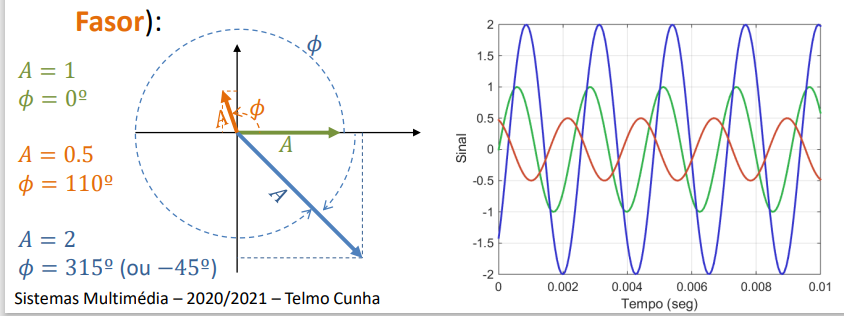

Fasores podem ser representados por números complexos. Utiliza-se o $\cos \left(\ldotp \right)$ para referir a fase.

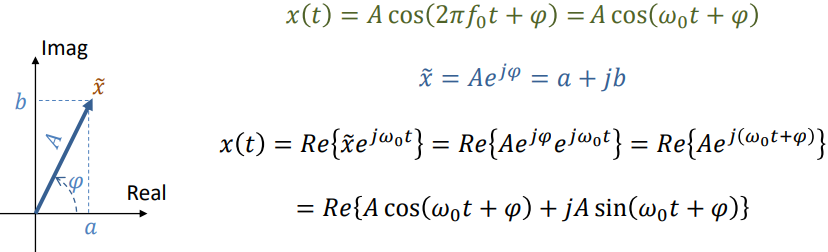

### Relembrar operações com números complexos para gente muito ceguinha

Cartesiano: $z=a+jb$, com $a=A\;\cos \left(\phi \right)$ e $b=A\;\sin \left(\phi \right)$

Polar: $z=Ae^{j\phi }$, com $A=\sqrt{\;a^2 +b^2 }$, $\phi =\textrm{atan}\left(\frac{b}{a}\right)$

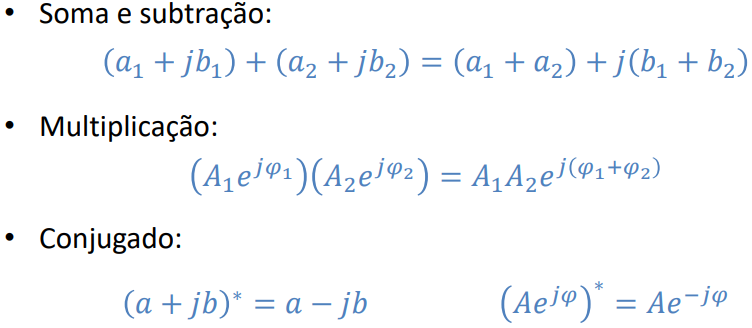

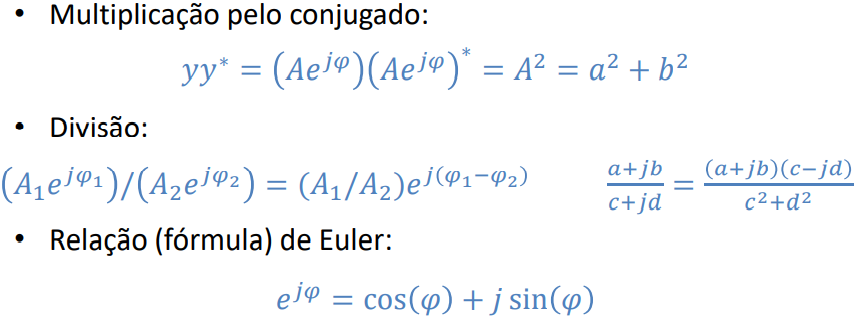

### Adição de sinusoides

Se tiverem a mesma frequência $f_0$, basta somar os fatores:

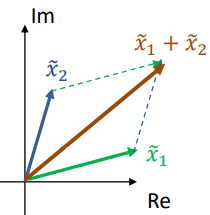 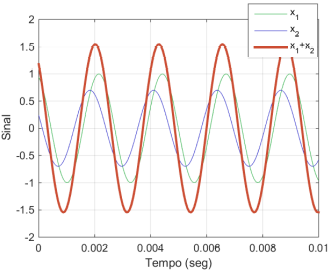

### Resposta sinusoidal de processos lineares

É analisada pela alteração de amplitude e de fase: $ỹ=\left(Ge^{j\delta } \right)\tilde{x} =\left(G\;A\right)e^{j\left(\phi +\delta \right)}$

### Potência de um sinal

Pode ser determinado por $\frac{A^2 }{2}$ ou por $\int_0^{T_0 } {\left|f\left(t\right)\right|}^2 \;\textrm{dt}$. Tendo o vetor de x, calcula-se assim:

function Pm = potencia(x,Ta,T)
N = T / Ta;
Pm = x(1:N)*x(1:N)'/N;
end

## Decomposição em série de sinusoides

Um sinal periódico pode ser descrito por um somatório de frequências múltiplas: $x\left(t\right)=\sum_{k=0}^K A_k \;\cos \left(2\pi \ldotp k\ldotp f\ldotp t+\phi_k \right)=\sum_{k=0}^K A_k \;\cos \left(2\pi \ldotp k\ldotp f\ldotp t+\phi_k \right)$

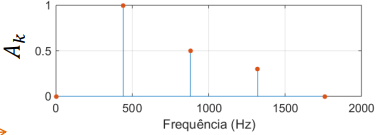

### Série de Fourier


$$x\left(t\right)=\sum_{k=0}^K a_k \;\cos \left(2\pi \ldotp k\ldotp f\ldotp t\right)+\sum_{k=1}^K b_k \;\sin \left(2\pi \ldotp k\ldotp f\ldotp t\right)$$


## Composição de sinusoides não harmonicamente relacionadas


$$x\left(t\right)=\sum_{k=1}^K A_k \;\cos \left(\omega_k t+\phi_k \right)$$


Frequência da nova sinusoide: $f_0 =\textrm{mdc}\left(f_1 ,f_2 ,\ldots,f_K \right)$. Se não houver mdc, o sinal composto não é periódico.

### Funções importantes em MATLAB

Calcular a potência:

function Pm = ex1_3(x,Ta,T)
N = T / Ta;
Pm = x(1:N)*x(1:N)'/N;
end

## Série e Transformada Discreta de Fourier (DFT)


$$x\left(t\right)=\sum_{k=0}^K a_k \;\cos \left(2\pi \ldotp k\ldotp f\ldotp t\right)+\sum_{k=1}^K b_k \;\sin \left(2\pi \ldotp k\ldotp f\ldotp t\right)=\sum_{k=0}^K A_k \;\cos \left(2\pi \ldotp k\ldotp f\ldotp t+\phi_k \right)$$



$$a_k =\frac{2}{T}\int_0^T x\left(t\right)\;\cos \left(2\pi \ldotp k\ldotp f\ldotp t\right)\;\textrm{dt};\;\;$$

$$a_0 =\frac{1}{T}\int_0^T x\left(t\right)\;\textrm{dt};\;\;$$

$$\forall k>0$$



$$b_k =\frac{2}{T}\int_0^T x\left(t\right)\;\sin \left(2\pi \ldotp k\ldotp f\ldotp t\right)\;\textrm{dt};\;\;$$

$$b_0 =0;\;\;$$

$$\forall k>0$$



$$A_k =\sqrt{\;a_k^2 +b_k^2 };\;\;$$

$$\phi_k =-\textrm{atan2}\left(\frac{b_k }{a_k }\right)$$


$t=n\times T_a$ (Substituir nas expressões. Nos coeficientes, substituir $t$ por $n$ e $\int_0^T \left(\ldots\right)\;\textrm{dt}$por $\sum_{n=1}^N \left.\right)$


$$N=\frac{T}{T_a }$$


N = Np/(f0*Ta);
t = (0:N-1)*Ta;

### Funções importantes em MATLAB

Produzir sinal resultante da série de Fourier:

function [t,x] = plotFourier(Ta,f0,Np,ak,bk)
K = length(ak);
N = Np/(f0*Ta);
t = (0:N-1)*Ta;

x = ak(1)*cos(2*pi*0*f0*t); % b0=0

for k = 1:K-1
    x = x + ak(k+1)*cos(2*pi*k*f0*t) + bk(k+1)*sin(2*pi*k*f0*t);
end

plot(t,x)
end

Calcular $a_k$ e $b_k$ de um sinal periódico $x\left(n\right)$:

function [ak,bk] = calculateCoefficients(Ta,T0,x,K)
k = K; N = K;
ak = 0;
bk = 0;
for n = 1:K
    ak = ak + x(n)*cos(2*pi*k*(1/T0)*n*Ta);
    bk = bk + x(n)*sin(2*pi*k*(1/T0)*n*Ta);
end
ak = 2/N .* ak;
bk = 2/N .* bk;
end

ou (?)

function [ak,bk] = ex3_t(Ta,T0,x,K)
Fa = 1/Ta;
F0 = 1/T0;
N = length(x);

ak = 0;
bk = 0;

for n = 1:N
    ak = ak + x(n) * cos(K*2*pi*F0*n);
    bk = bk + x(n) * sin(K*2*pi*F0*n);
end
ak = 2/T0 .* ak;
bk = 2/T0 .* bk;
end

### Aplicação da Fórmula de Euler (Série Exponencial de Fourier)


$$x\left(t\right)=\sum_{k=-K}^K C_k \;e^{j\ldotp 2\pi k\ldotp f\ldotp t} ,\;C_k \in \mathbb{C}$$


Passa a existir o conceito de frequências "positivas" e "negativas", bem como o conceito de **Espetro** (conteúdo ao longo da frequência).

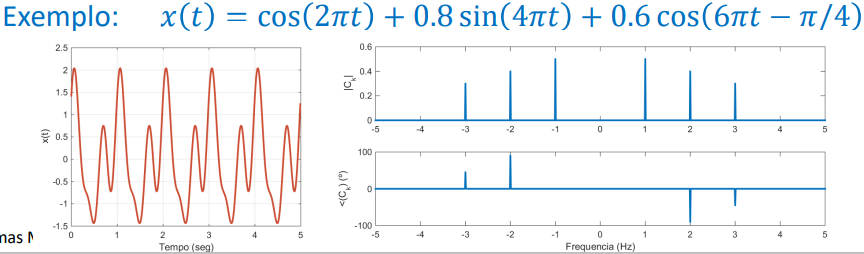

### Exemplos da aplicação da DFT

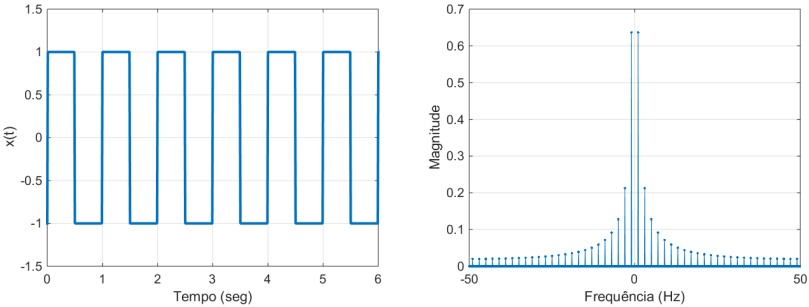    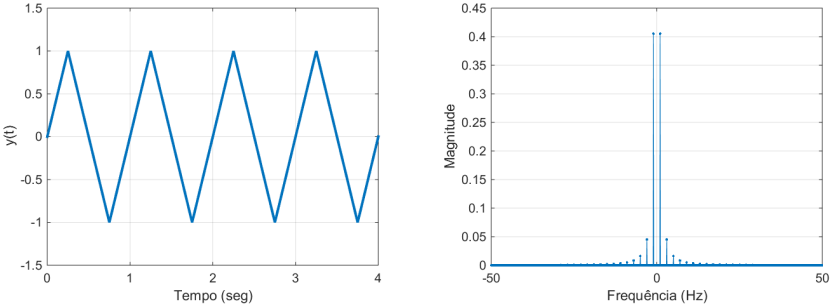

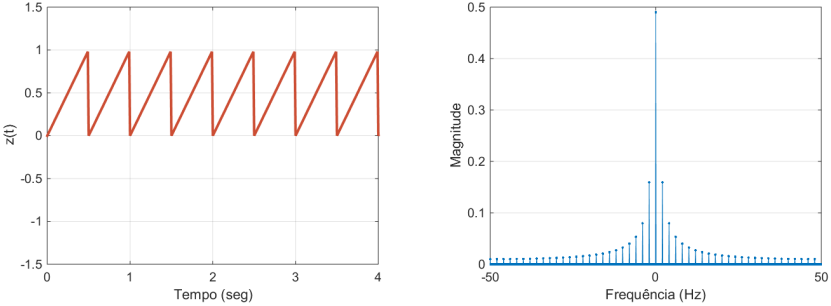    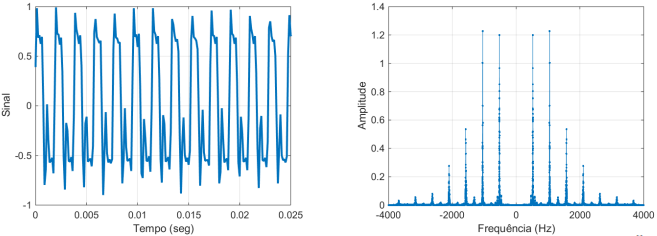

### DFT em sinais não periódicos

Existem técnicas para forçar sinais a serem considerados como periódicos. A mais usada é a de *windowing*.

A DFT pode ser aplicada a uma sequência de amostras (repetidas):

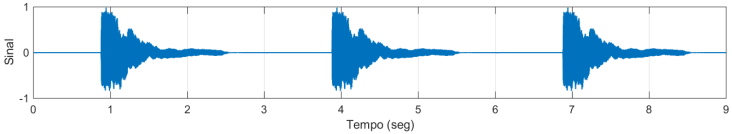

*Windowing* aplica-se quando a parte inicial da sequência não tem continuidade na final:

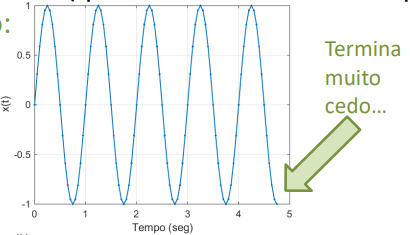

Portanto, *windowing* consiste em multiplicar a sequência por uma "janela" que força a forma periódica:

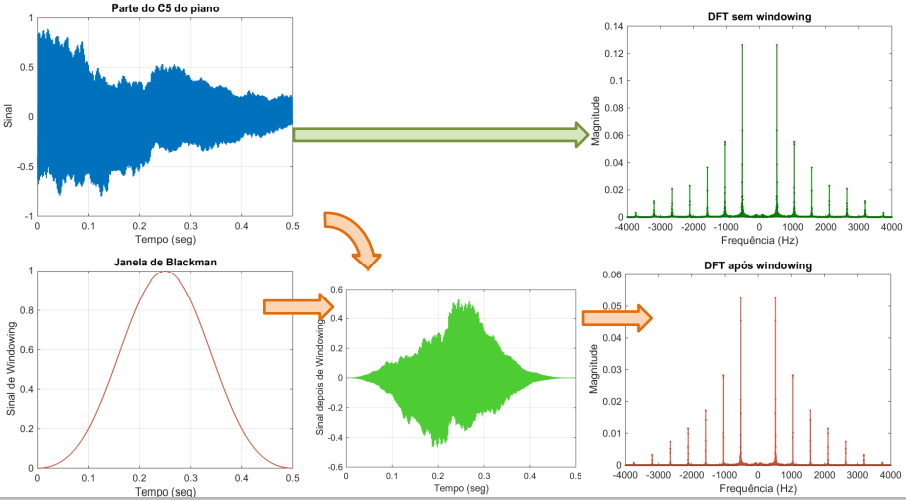

### Algoritmo FFT (Fast Fourier Transform)

Seja $x$ um vetor de $N$ amostras consecutivas de um sinal, com período de amostragem $T_a$:

X = fft(x)/N;

O vetor $X$ tem $N$ elementos. O vetor de frequências correspondente a $X$ é:

f = 0:df:(N-1)*df; % ou f = (0:N-1)*df

Pode-se usar `fftshift(X)` para ordenar de $-\frac{f_a }{2}$ a $\frac{f_a }{2}$.

### Funções importantes em MATLAB

Apresentar o espetro de um sinal:

function [X,f] = espetro(x,Ta)
% X é vetor da mesma dimensão de x, com coeficientes da DFT de x(t)
% f é vetor da mesma dimensão de x, com as frequências de cada componente de X
N = length(x);
Fa = 1/Ta;

f = (0:N-1)*Fa/N - Fa/2; % ou f = -Fa/2:Fa/N:Fa/2;
X = fftshift(fft(x))/N;

plot(f,abs(X))
xlim([-Fa/2,Fa/2])
xlabel('Frequência (Hz)')
ylabel('Amplitude')
end

Função inversa da função anterior:

function x = reconstroi(X)
N = length(X);
x = ifft(fftshift(X))*N;
end

## Espetrograma

Uma sequência de tons diferentes tem um espetro idêntico ao dos mesmos tons considerados em simultâneo:

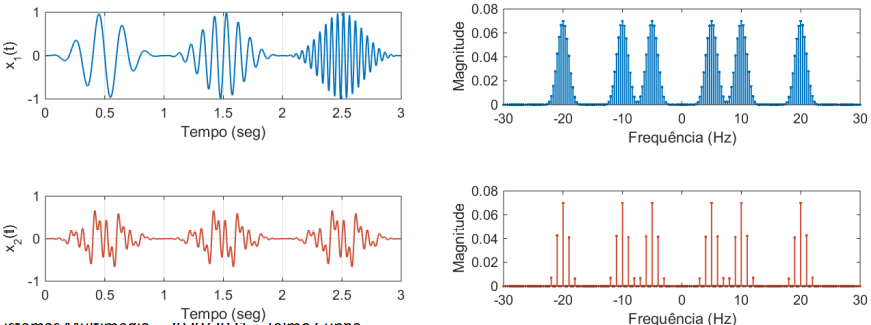

Nestes casos, é usual considerar-se a short-time FFT, cujo resultado é conhecido por Espetrograma.

spectrogram('…');